# Chapter 1: Wavelet Transform

Most signals in practical applications are captured in the **time domain**, meaning that they represent how a measured variable changes over time. Typically, these signals are plotted with **time** on the x-axis and **amplitude** on the y-axis. While time-domain representations provide valuable information, they are often not the most suitable format for advanced signal processing tasks. The crucial details may lie not in the time-domain behavior, but in the signal’s **frequency content**—a set of components that describe how different frequencies combine to form the overall signal.

In signal processing, understanding the frequency components of a signal helps reveal hidden information that is not apparent in the time-domain representation. This is particularly important because many signals contain essential details encoded in their **frequency spectrum**, which describes the distribution of various frequencies within the signal. By transforming a signal from the time domain into the frequency domain, we can uncover patterns and features that are crucial for various applications, such as communications, medical diagnostics, and audio processing.

In signal analysis, obtaining frequency information is essential because certain features of a signal that are not easily detected in the time-domain can become evident when analyzed in the frequency domain. This section discusses the relevance of frequency information, particularly through the example of biological signals, and explores the use of different transformation techniques, including Fourier and wavelet transforms, for obtaining this information.

**The Need for Frequency Information**

Consider the case of an **ElectroCardiography (ECG)** signal, which represents the electrical activity of the heart. A healthy ECG signal has a characteristic shape that cardiologists recognize easily. However, deviations from this typical pattern, indicative of pathological conditions, may not always be obvious when viewed in the time domain alone. In such cases, analyzing the frequency content of the signal can help reveal hidden abnormalities.

While traditional ECG analysis relies heavily on visual inspection of time-domain signals recorded on strip charts, modern computerized ECG analyzers now incorporate frequency-domain analysis to better detect potential heart conditions. A pathological condition, which may go unnoticed in the time-domain signal, can often be diagnosed more effectively when the frequency content is examined.

This example underscores the broader importance of frequency analysis in medical diagnostics. Beyond biological signals, the use of frequency analysis, particularly through Fourier transforms, spans across various branches of engineering and scientific disciplines, allowing for deeper insights into complex signals.

**Fourier Transform and Alternatives**

The **Fourier Transform (FT)** is one of the most commonly used methods for transforming time-domain signals into the frequency domain, particularly in electrical engineering. However, it is not the only transformation available. Engineers and mathematicians have developed many other techniques, including the **Hilbert transform**, **short-time Fourier transform (STFT)**, **Wigner distributions**, **Radon transform**, and the **wavelet transform (WT)**. Each of these transformations has specific advantages and disadvantages, depending on the type of signal being analyzed and the information needed.

The **Wavelet Transform (WT)**, in particular, provides a more flexible alternative to the FT in certain applications, especially when analyzing non-stationary signals. While the FT is excellent at revealing the frequency components of a signal, it does not provide information on when these components occur over time, which limits its usefulness for signals that change in frequency.

**Stationary vs. Non-Stationary Signals**

To understand the limitations of the Fourier Transform, it is crucial to differentiate between **stationary** and **non-stationary** signals. A stationary signal has frequency components that do not change over time, meaning that all frequency components exist throughout the signal's duration. In such cases, the Fourier Transform works well because the time information is irrelevant—what matters is the signal's overall frequency content.

However, many real-world signals are **non-stationary**, meaning that their frequency content changes over time. In such cases, the FT becomes inadequate, as it does not provide any insight into when these frequency changes occur. This is where the **wavelet transform** excels, as it allows for both time and frequency information to be analyzed simultaneously.**The Importance of Time-Frequency Analysis**

While the FT gives a complete view of the frequency components, it fails to indicate when these components occur within the signal. This lack of time information becomes critical in non-stationary signals, where the timing of frequency events is as important as the frequency content itself. The ability to examine both time and frequency characteristics is essential for tasks such as speech analysis, seismic signal processing, and certain biomedical applications, where the signal's behavior can vary significantly over time.

In conclusion, frequency analysis is a fundamental aspect of signal processing, particularly when dealing with complex or non-stationary signals. The Fourier Transform offers a powerful method for frequency analysis, but it is not always sufficient on its own. The wavelet transform and other alternative techniques provide valuable tools for analyzing signals in both the time and frequency domains, giving engineers and scientists the ability to gain deeper insights into signal behavior.

**Mathematical Transformations in Signal Processing: Fourier Transform, Short-Time Fourier Transform, and Wavelet Transform**

Mathematical transformations play a pivotal role in signal processing by enabling the analysis and manipulation of signals in domains that reveal essential characteristics not immediately apparent in their original form. This section presents the fundamental formulas for three widely used transformations: the **Fourier Transform (FT)**, the **Short-Time Fourier Transform (STFT)**, and the **Wavelet Transform (WT)**. Each transformation offers unique insights into the frequency and time-frequency content of signals, facilitating diverse applications across engineering and scientific disciplines.

**1. Fourier Transform (FT)**

The **Fourier Transform** decomposes a time-domain signal into its constituent frequency components, providing a frequency-domain representation. It is instrumental in analyzing the spectral content of signals, filtering, and solving differential equations.

**Definition:**

For a continuous-time signal x(t), the Fourier Transform X(f) is defined as:


$$X(f) = \int_{-\infty}^{\infty} x(t) e^{-j 2 \pi f t} \, dt
$$


**Inverse Fourier Transform:**

To reconstruct the original time-domain signal from its frequency-domain representation, the **Inverse Fourier Transform** is used:


$$x(t) = \int_{-\infty}^{\infty} X(f) e^{j 2 \pi f t} \, df
$$


**2. Short-Time Fourier Transform (STFT)**

The **Short-Time Fourier Transform** extends the Fourier Transform by analyzing localized sections of a signal, making it suitable for non-stationary signals whose frequency content evolves over time.

**Definition:**

For a continuous-time signal x(t) and a window function w(t) centered at time tau, the STFT X(τ,f) is defined as:


$$\text{STFT}(t, f) = \int_{-\infty}^{\infty} x(\tau) w(\tau - t) e^{-j 2 \pi f \tau} \, d\tau
$$


**Key Features:**

- **Time-Frequency Localization:** Provides information about how the frequency content of a signal changes over time.

- **Window Function:** The choice of window w(t) affects the time and frequency resolution, governed by the **Heisenberg Uncertainty Principle**.

**Applications:**

- Speech processing

- Music analysis

- Biomedical signal analysis (e.g., EEG, ECG)

**3. Wavelet Transform (WT)**

The **Wavelet Transform** offers a multi-resolution analysis of signals, capturing both time and frequency information with varying resolutions. It is particularly effective for analyzing non-stationary signals with transient features.

**Continuous Wavelet Transform (CWT):**

For a continuous-time signal x(t), the CWT W(a,b) is defined using a mother wavelet ψ(t):


$$W_x(a,b) = \frac{1}{\sqrt{|a|}} \int_{-\infty}^{\infty} x(t) \psi^*\left(\frac{t - b}{a}\right) \, dt
$$


- **Scale **a**:** Controls the dilation (stretching) of the wavelet; larger scales correspond to lower frequencies.

- **Translation **b**:** Controls the shifting of the wavelet in time.

- ψ***:** Complex conjugate of the mother wavelet.

**Key Advantages:**

- **Multi-Resolution Analysis:** Offers both high-frequency and low-frequency resolution, adapting to the signal's features.

- **Sparsity:** Represents signals more efficiently, especially those with transient or localized features.

- **Time-Frequency Localization:** Similar to STFT but with variable window sizes, providing better localization for different frequency bands.

**Applications:**

- Image compression

- Feature extraction in machine learning

- Medical signal analysis (e.g., detecting anomalies in ECG)

- Geophysical data analysis

**Summary of Transformations**

Each transformation serves distinct purposes:

- **FT:** Ideal for stationary signals where frequency content does not change over time.

- **STFT:** Suitable for non-stationary signals requiring localized time-frequency analysis with fixed resolution.

- **WT:** Best for signals with transient features, offering adaptive time-frequency resolution.

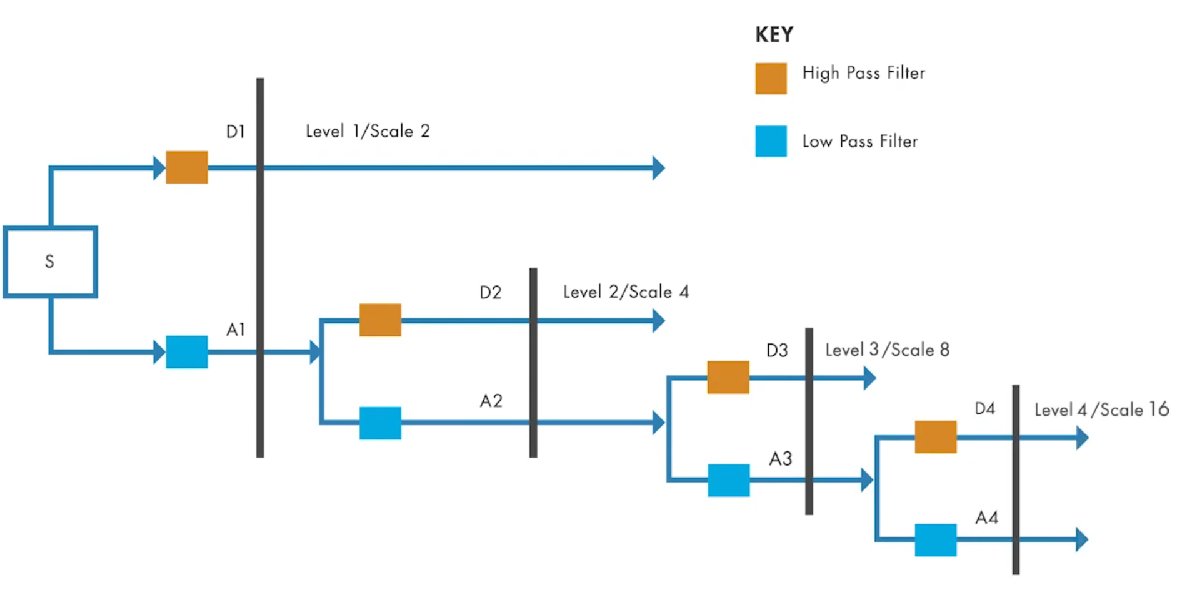

Let us start with the FT of a stationary signal: stationary signal is defined as a signal whose frequency component does not changes with time.

Following is the example of a stationary signal having frequency components of 10Hz, 20Hz, 50Hz and 100Hz all existing at all times in the signal.

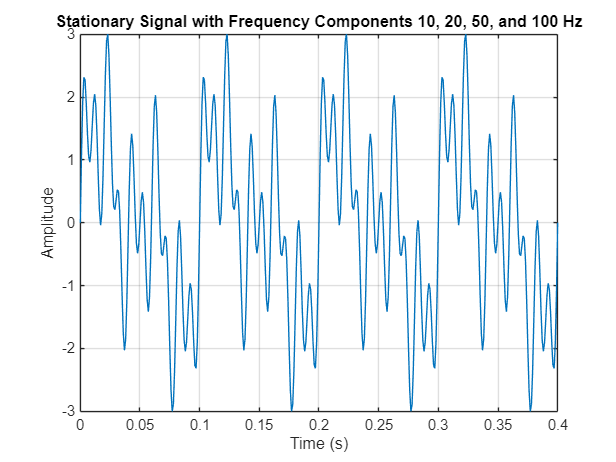

% Parameters
fs = 1000;              % Sampling frequency (Hz)
t = 0:1/fs:0.4;          % Time vector from 0 to 1 second
frequencies = [10, 20, 50, 100]; % Frequency components (Hz)

% Generate the stationary signal
signal = zeros(size(t)); % Initialize the signal
for f = frequencies
    signal = signal + sin(2 * pi * f * t); % Sum the sine waves
end

% Plot the signal
figure;
plot(t, signal);
title('Stationary Signal with Frequency Components 10, 20, 50, and 100 Hz');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
axis tight;

Let us now Perform the Fourier Transform of the signal.

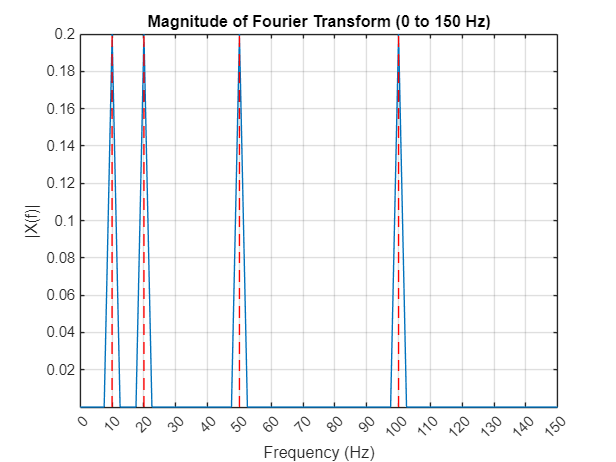

% Define frequency vector for FT computation
f = linspace(0, fs/2, length(t)/2+1);  % Frequency vector for positive frequencies
X = zeros(size(f)); % Initialize Fourier Transform result

% Compute Fourier Transform using numerical integration
dt = 1/fs; % Time increment
for k = 1:length(f)
    % Use the definition of Fourier Transform
    X(k) = sum(signal .* exp(-1j * 2 * pi * f(k) * t)) * dt;
end

% Limit the frequency and transform to only positive frequencies up to 150 Hz
f_limit = f(f <= 150);
X_limit = X(f <= 150);

% Plot the magnitude of the Fourier Transform (only positive frequencies up to 150 Hz)
plot(f_limit, abs(X_limit));
title('Magnitude of Fourier Transform (0 to 150 Hz)');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;
axis tight;

% Add markers at 10, 20, 50, and 100 Hz
hold on;
y_limits = ylim; % Get current y-axis limits
for freq = frequencies
    plot(freq * [1 1], y_limits, 'r--'); % Vertical dashed lines
end
xticks(0:10:150); % Set x-ticks at intervals of 10 Hz
hold off;

Chirp signal

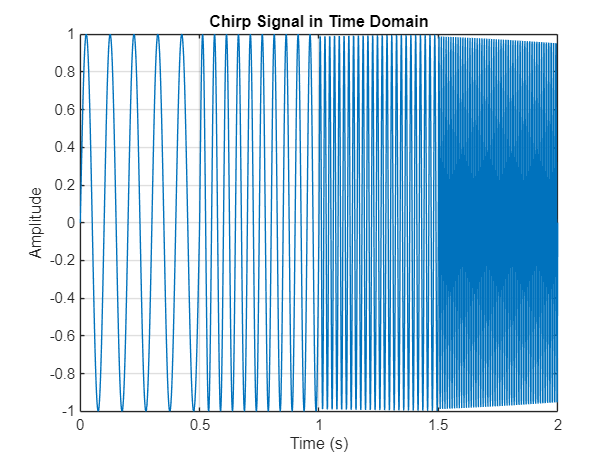

% Chirp Signal: 10 Hz, 20 Hz, 50 Hz, 100 Hz in Time Domain
% Parameters
Fs = 1000;        % Sampling frequency in Hz
T = 2;            % Total duration in seconds
t = linspace(0, T, T*Fs);  % Time vector

% Define time intervals for each frequency segment
t1_end = 0.5;  % End of first segment (seconds)
t2_end = 1.0;  % End of second segment (seconds)
t3_end = 1.5;  % End of third segment (seconds)
t4_end = 2.0;  % End of fourth segment (seconds)

% Boolean masks for each segment
segment1 = (t >= 0) & (t < t1_end);
segment2 = (t >= t1_end) & (t < t2_end);
segment3 = (t >= t2_end) & (t < t3_end);
segment4 = (t >= t3_end) & (t <= t4_end);

% Initialize chirp signal array
chirp_signal = zeros(size(t));

% Generate chirp segments
chirp_signal(segment1) = sin(2 * pi * 10 * t(segment1));   % 10 Hz
chirp_signal(segment2) = sin(2 * pi * 20 * t(segment2));   % 20 Hz
chirp_signal(segment3) = sin(2 * pi * 50 * t(segment3));   % 50 Hz
chirp_signal(segment4) = sin(2 * pi * 100 * t(segment4));  % 100 Hz

% Plot the chirp signal in time domain
figure;
plot(t, chirp_signal);
title('Chirp Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
xlim([0 T]);

FT of chirp signal

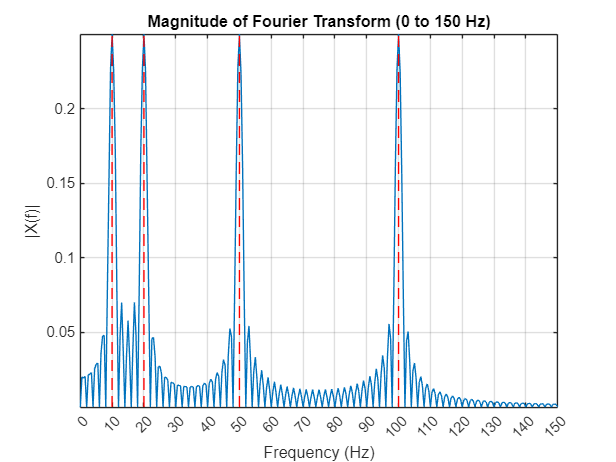

% Perform Fourier Transform using numerical integration
dt = 1/Fs; % Time increment
f = linspace(0, Fs/2, length(t)/2+1);  % Frequency vector for positive frequencies

X = zeros(size(f)); % Initialize Fourier Transform result

for k = 1:length(f)
    % Use the definition of Fourier Transform
    X(k) = sum(chirp_signal .* exp(-1j * 2 * pi * f(k) * t)) * dt;
end

% Limit the frequency and transform to only positive frequencies up to 150 Hz
f_limit = f(f <= 150);
X_limit = X(f <= 150);

% Plot the magnitude of the Fourier Transform (only positive frequencies up to 150 Hz)
figure;
plot(f_limit, abs(X_limit));
title('Magnitude of Fourier Transform (0 to 150 Hz)');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;
axis tight;

% Add markers at 10, 20, 50, and 100 Hz
hold on;
frequencies = [10, 20, 50, 100];
y_limits = ylim; % Get current y-axis limits
for freq = frequencies
    plot(freq * [1 1], y_limits, 'r--'); % Vertical dashed lines
end
xticks(0:10:150); % Set x-ticks at intervals of 10 Hz
hold off;

STFT

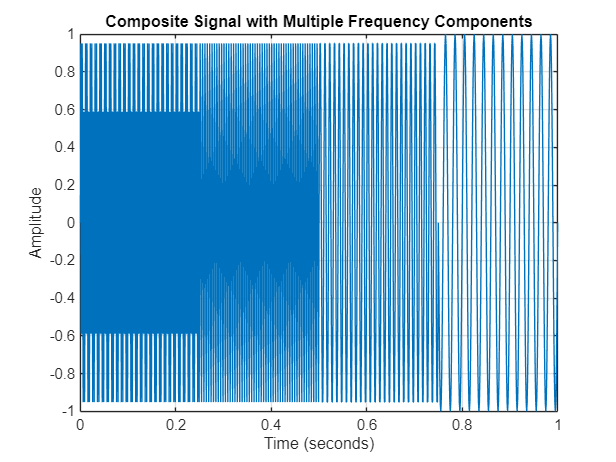

% Parameters
fs = 1000;               % Sampling frequency (Hz)
t = 0:1/fs:1;           % Time vector from 0 to 1 second
signal = zeros(size(t)); % Initialize the signal

% Create the signal with different frequency components
signal(1:250*fs/1000) = sin(2*pi*300*t(1:250*fs/1000));  % 300 Hz
signal(251*fs/1000:500*fs/1000) = sin(2*pi*200*t(251*fs/1000:500*fs/1000));  % 200 Hz
signal(501*fs/1000:750*fs/1000) = sin(2*pi*100*t(501*fs/1000:750*fs/1000));  % 100 Hz
signal(751*fs/1000:end) = sin(2*pi*50*t(751*fs/1000:end));  % 50 Hz
% Plot the signal
figure;
plot(t, signal);
title('Composite Signal with Multiple Frequency Components');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

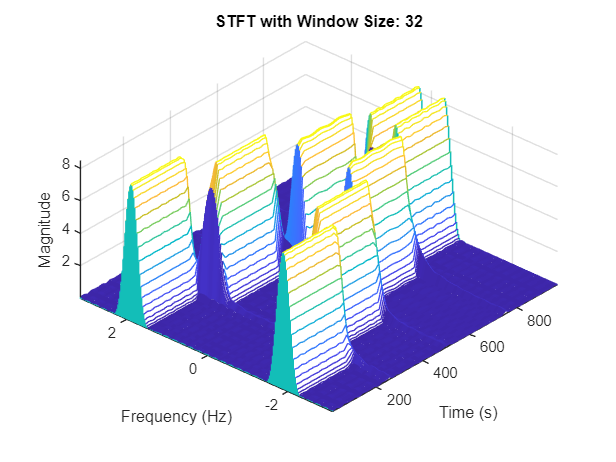

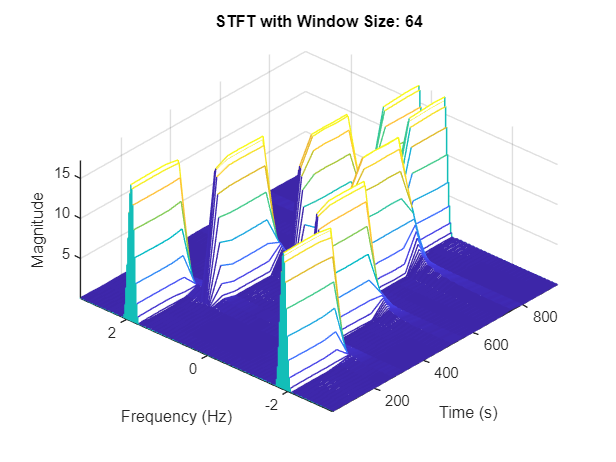

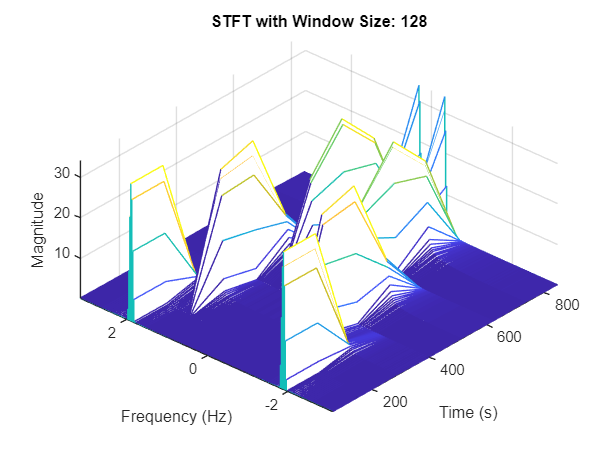


% Window sizes
window_sizes = [32, 64, 128]; % Narrow, Medium, Wider windows
overlap = 16;                  % 50% overlap for STFT

for i = 1:length(window_sizes)
    window = hamming(window_sizes(i)); % Hamming window
    [S, F, T] = stft(signal, 'Window', window, 'OverlapLength', overlap, 'FFTLength', 256);

    % Create the waterfall plot
    figure;
    waterfall(T, F, abs(S));
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    zlabel('Magnitude');
    title(['STFT with Window Size: ' num2str(window_sizes(i))]);
    axis tight; % Adjust axis limits to focus on the data
    % view(45, 30); % Set a view angle for better visualization
    view([-48.34 51.00])
    grid on; % Add grid for better readability
end

Wavelet Transform

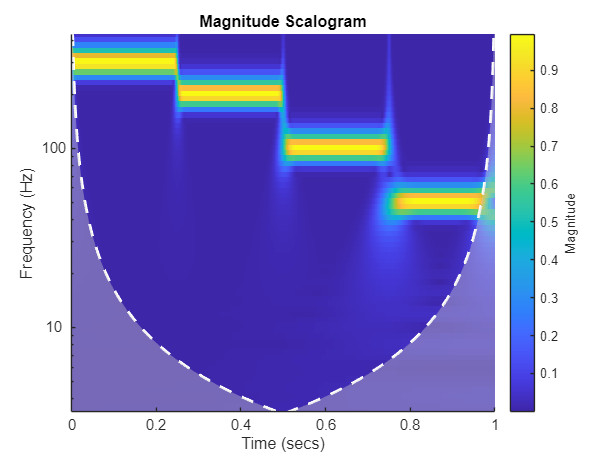

% Define parameters
samplingRate_1 = 1000; % Assuming 1 second corresponds to 1000 data points

cwt(signal,1000);

# Chapter 2: Seizure and EEG Signals:

Electroencephalography (EEG) is a non-invasive technique used to record electrical activity of the brain. EEG measures voltage fluctuations resulting from ionic current flows within the neurons of the brain. It captures brain wave patterns, which are essential for diagnosing and studying brain conditions and activities.

**Who Introduced EEG First:**

EEG was first introduced by **Hans Berger**, a German psychiatrist, in **1929**. Berger was the first to record human brain electrical activity and identify the brain's rhythmic oscillations, which he termed "brain waves."

**How EEG is Recorded:**

EEG is recorded using electrodes placed on the scalp. These electrodes detect the small electrical signals produced by neuronal activity. The signals are then amplified and displayed as a waveform on a computer or an oscilloscope. The standard electrode placement follows the **10-20 system**, which provides consistent and reproducible electrode positions for EEG recording.

**Bipolar and Unipolar Method:**

- **Bipolar Method**: In bipolar EEG recordings, the difference in electrical potential between two active electrodes placed at different scalp locations is measured. This provides a differential signal that reflects the relative brain activity between the two electrodes.

- **Unipolar Method**: In the unipolar or monopolar method, one electrode is placed over the scalp (the active electrode) and referenced against a common point (often the average of all electrodes or a neutral reference). This method reflects the absolute electrical activity at each electrode site relative to a reference.

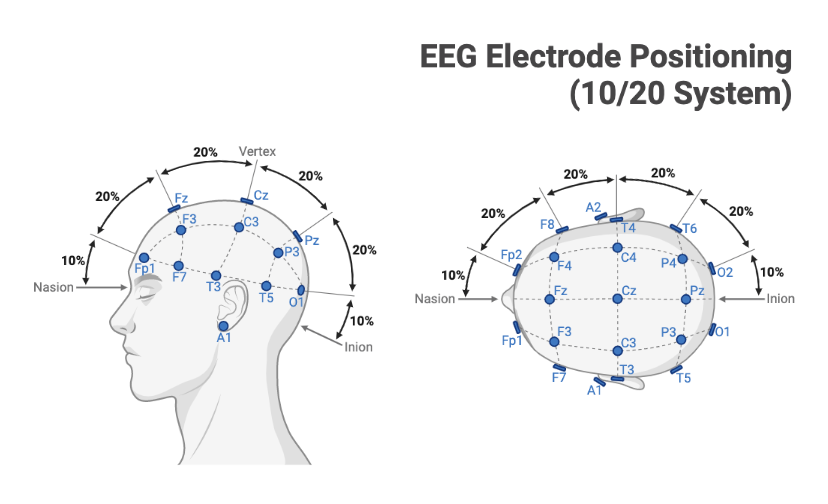

**Source of EEG:**

EEG signals originate from the synchronous activity of **cortical neurons** in the brain. The primary source of these signals is the post-synaptic potentials of pyramidal neurons in the cerebral cortex. These neurons generate electrical potentials that travel through the brain tissue, skull, and scalp to the electrodes on the surface of the head.

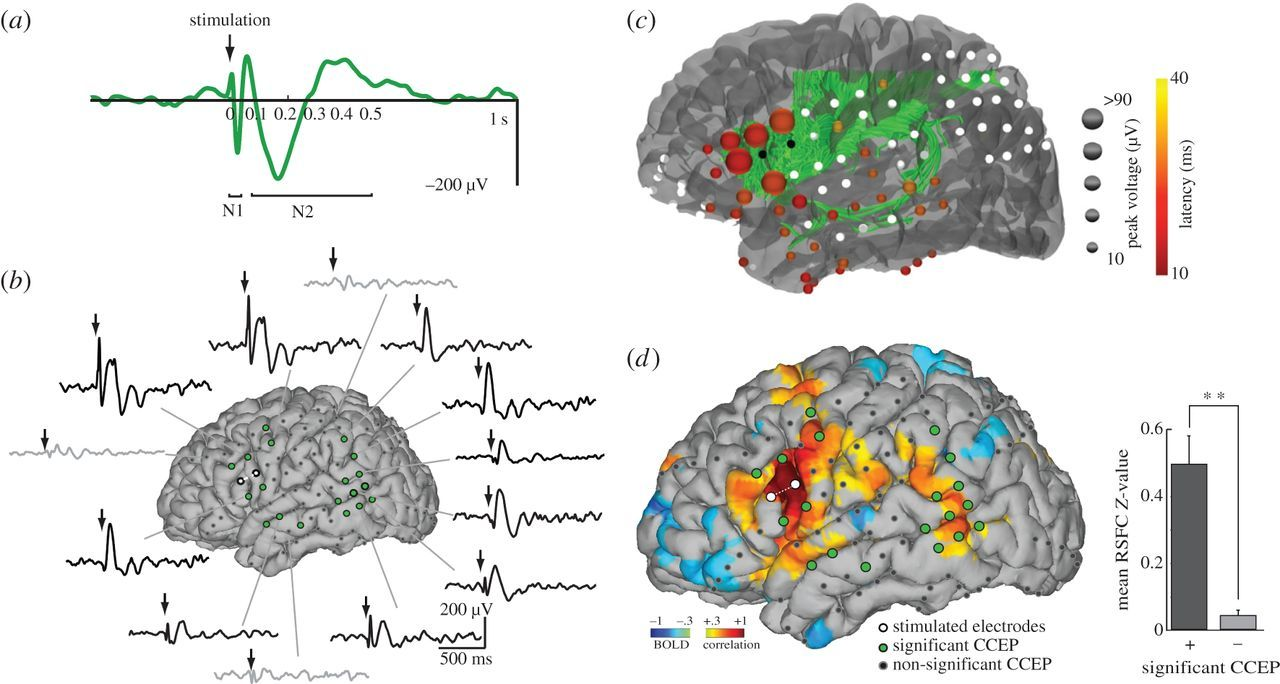

**Uses of EEG:**

EEG has a wide range of clinical and research applications, including:

- **Diagnosis of Neurological Disorders**: EEG is commonly used to diagnose and monitor epilepsy, sleep disorders, brain tumors, stroke, and other neurological conditions.

- **Monitoring Brain Activity**: In the operating room, EEG is used to monitor brain function during anesthesia or neurosurgical procedures.

- **Sleep Studies**: EEG helps in understanding different sleep stages and diagnosing sleep disorders like insomnia, narcolepsy, or sleep apnea.

- **Brain-Computer Interfaces (BCI)**: EEG is used in developing systems that allow direct communication between the brain and external devices.

- **Cognitive and Behavioral Research**: EEG is used in psychology and neuroscience to study attention, memory, emotion, and other cognitive processes.

- **Coma and Brain Death**: EEG is useful in assessing brain activity in comatose patients to determine brain function or brain death.

**Epilepsy** is a neurological disorder characterized by recurrent seizures, which are caused by excessive and abnormal electrical discharges from cerebral neurons. The diagnosis of epilepsy typically involves the analysis of EEG patterns, where epileptic foci generate high-voltage (amplitude) waves. These abnormal waves can help in localizing the source of seizures and determining the type of epilepsy.

**Forms of Epilepsy**

- **Grand Mal Epilepsy (Tonic-Clonic Seizures)**:

- **Description**: Grand mal epilepsy, also known as tonic-clonic seizures, is characterized by a loss of consciousness and violent muscle contractions. It is the most severe form of seizure and involves two phases: the tonic phase, where the body stiffens, and the clonic phase, where rhythmic jerking of the limbs occurs.

- **Symptoms**: Patients may experience an aura (a warning sign) before the seizure, followed by loss of consciousness, tongue biting, and postictal confusion (confusion after the seizure).

- **EEG Findings**: During the seizure, EEG shows generalized high-voltage spikes followed by slow waves. Interictally (between seizures), the EEG may show spikes or sharp waves.

- **Petit Mal Epilepsy (Absence Seizures)**:

- **Description**: Petit mal epilepsy, also known as absence seizures, is characterized by brief, sudden lapses of consciousness. These seizures typically last for a few seconds and may occur multiple times a day.

- **Symptoms**: Patients may appear to "blank out" or stare into space during an absence seizure. There is usually no postictal confusion, and the patient quickly resumes normal activity afterward.

- **EEG Findings**: The hallmark of absence seizures is the presence of 3 Hz spike-and-wave discharges on the EEG during the seizure. Interictally, these spike-and-wave patterns can also be seen.

- **Psychomotor Epilepsy (Temporal Lobe Epilepsy)**:

- **Description**: Psychomotor epilepsy, often referred to as temporal lobe epilepsy, involves complex partial seizures that can affect behavior, emotion, and memory. These seizures often originate from the temporal lobe of the brain.

- **Symptoms**: Patients may exhibit automatic behaviors (such as lip-smacking, fumbling, or walking in circles) and may not be aware of their surroundings during the seizure. There may be a postictal state of confusion or amnesia.

- **EEG Findings**: The EEG may show focal spikes or sharp waves in the temporal lobe region, especially during the seizure. Interictally, there may be abnormal findings in the temporal areas.